# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Luke\Simon\RawData_All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = true;                                                       % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Luke\Simon\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[14 15] [16 45 46 19] [37 38] [31 34] [23 24]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq                                                               % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = 1;

Deci.DT.Block.Markers   = {40};

% Cell Array of Markers for Block Starts

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [1 50];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';


Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.AddComponents =  false;

## 4. Analysis

LockTypes = {'Simon_Cor' 'Simon_Con' 'Simon_Side' 'Simon_Contra'};

## 5. Plotting

## ** 6. Run**

Channel AF3 1 of 58
Channel AF4 2 of 58
Channel AFz 3 of 58
Channel C1 4 of 58
Channel C2 5 of 58
Channel C3 6 of 58
Channel C4 7 of 58
Channel C5 8 of 58
Channel C6 9 of 58
Channel CP1 10 of 58
Channel CP2 11 of 58
Channel CP3 12 of 58
Channel CP4 13 of 58
Channel CP5 14 of 58
Channel CP6 15 of 58
Channel CPz 16 of 58
Channel Cz 17 of 58
Channel F1 18 of 58
Channel F2 19 of 58
Channel F3 20 of 58
Channel F4 21 of 58
Channel F5 22 of 58
Channel F6 23 of 58
Channel F7 24 of 58
Channel F8 25 of 58
Channel FC1 26 of 58
Channel FC2 27 of 58
Channel FC3 28 of 58
Channel FC4 29 of 58
Channel FC5 30 of 58
Channel FC6 31 of 58
Channel FCz 32 of 58
Channel FT7 33 of 58
Channel FT8 34 of 58
Channel Fz 35 of 58
Channel O1 36 of 58
Channel O2 37 of 58
Channel Oz 38 of 58
Channel P1 39 of 58
Channel P2 40 of 58
Channel P3 41 of 58
Channel P4 42 of 58
Channel P5 43 of 58
Channel P6 44 of 58
Channel P7 45 of 58
Channel P8 46 of 58
Channel PO3 47 of 58
Channel PO4 48 of 58
Channel PO7 49 of 58
Channel

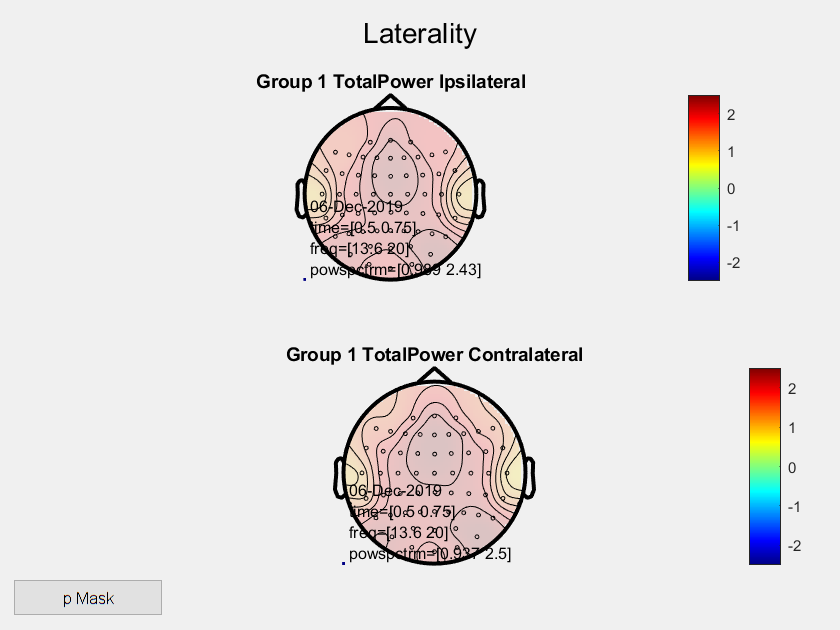

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

if Deci.Step == 4
    for AnalysisLocks = LockTypes
        eval(AnalysisLocks{1})
        
        
        Deci.SubjectList        = 'gui';
        
        Deci_Wavelet;
        
        Deci.Analysis.Freq.do  = true;
        Deci_Backend(Deci);
        
    end
else
    
    Simon_Contra;
    Deci.Plot.BslRef = 'Rsp Onset';
    Deci.Plot.Lock =  'Rsp Onset';
    
    Deci.Plot.GrandAverage = true;
    
    Deci.Plot.Freq.Topo.do    =true;
    Deci.Plot.Freq.Topo.Foi     = [13 21];                   % Frequency of Interest
    Deci.Plot.Freq.Topo.Toi     = [.5 .75];                   % Time of Interest
    Deci.Plot.Freq.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Freq.Square.do  =false;
    Deci.Plot.Freq.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Freq.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Freq.Wire.do    =false;
    Deci.Plot.Freq.Wire.Foi     =   [4 7.5];          % Frequency of Interest
    Deci.Plot.Freq.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Wire.Channel = [{'Cz'}];              % Channel of Interest
    
    Deci.Plot.Freq.Bar.do    =false;
    Deci.Plot.Freq.Bar.Foi     = [4 7.5];                 % Frequency of Interest
    Deci.Plot.Freq.Bar.Toi     = [0 1];                   % Time of Interest
    Deci.Plot.Freq.Bar.Channel =  ['Reinhart-All'];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Response Onset')
        Deci.Plot.Freq.Bsl     = [-.5 -.3];
    else
        Deci.Plot.Freq.Bsl     = [-.5 0];
    end
    
    if  Deci.Plot.Freq.Square.do
        Omnibus = false;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.Freq.BslType = 'db'
            Deci.Plot.Stat.FPlots =  false;
        end
        Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Freq.Topo.do
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    end
    
    if Deci.Plot.Freq.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
     if Deci.Plot.Freq.Wire.do
        Deci.Plot.Stat.do = false;
    end
    
    Deci_Backend(Deci);
end